n = 40; %number of elements
y = linspace(0,1,n);
delta_y = y(2);
guessU = ones(n,1); %f(0)
guessU(1) = 0; guessU(n)=0;

E = 1;
I = 1;

% set up tridiagonal matrix A, which is based on central difference scheme
alpha = 1/delta_y^2;
beta = -2/delta_y^2;
a = alpha.*ones(n,1); a(n) = 0;
b = beta.*ones(n,1); b(1) = 1; b(n) = 1;
c = alpha.*ones(n,1); c(1) = 0;

residuals = 1;
tolerance = 1e-5;
newU = guessU;
lambdaOld = 0;
while residuals > tolerance
   oldU = newU;
   newU = THOMAS3(a,b,c,oldU,n)';
   lambda = (oldU'*newU)/(oldU'*oldU);
   newU = newU./sqrt(newU'*newU);
   residuals = max(abs(lambda-lambdaOld));
   lambdaOld = lambda;
end
u = newU;
1/lambda

ans = -9.8643

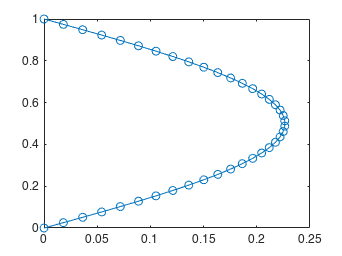

plot(u,y,'Marker','o')



% set up tridiagonal matrix A, which is based on central difference scheme
alpha = 1/delta_y^2;
beta = -2/delta_y^2;
a = alpha.*ones(n,1); a(n) = 0;
b = beta.*ones(n,1); b(1) = 1; b(n) = 1;
c = alpha.*ones(n,1); c(1) = 0;
A = diag(a(2:n),-1)+diag(b)+diag(c(1:n-1),1);

residuals = 1;
tolerance = 1e-5;
newU = guessU;
lambdaOld = 0;
while residuals > tolerance
   oldU = newU;
   newU = A*oldU;
   lambda = (oldU'*newU)/(oldU'*oldU);
   newU = newU./sqrt(newU'*newU);
   residuals = max(abs(lambda-lambdaOld));
   lambdaOld = lambda;
end
u = newU;
lambda

lambda = -6.0446e+03

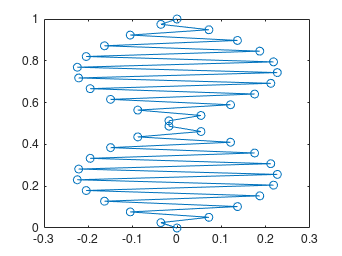

plot(u,y,Marker="o")

function x = THOMAS3(a,b,c,d,n) 

    %initial condition
    bbar(1) = b(1);
    cbar(1) = c(1);
    dbar(1) = d(1);

    %making upper triangle
    for i = 2:n
        multiplier = a(i)./bbar(i-1);
        abar(i) = a(i) - bbar(i-1).*multiplier;
        bbar(i) = b(i) - cbar(i-1).*multiplier;
        cbar(i) = c(i);
        dbar(i) = d(i) - dbar(i-1).*multiplier;
    end
    
    %initialize x of size n
    x = ones(1,n);

    %initialize end condition
    x(n) = dbar(n)/bbar(n);

    % Upward substitution AKA zip it up
    for i = n-1:-1:1
        x(i) = (dbar(i)-(cbar(i)*x(i+1)))/bbar(i);
    end
end